% Import data
data_HW3 = readtable("Top 100 Genes PF.xlsx","ReadRowNames",true);

% Inspect table
head(data_HW3,5)

ans = 5×103 table
                  SurvivalDays    SurvivalDaysPF    Test     LIX1L        NEU4       TTC12      IFITM10       EIF3L       DGCR14       MRPS27       KHDRBS3      CCDC89       PHB2       TTLL1      PPAPDC1A     TNNC2        WWP2      C2orf27A      USE1       FCHSD2      EEF1G      C20orf196    RPL19P12     LYSMD1       OLIG1       ZNF780A       LUZP2       MYO15A       RPL3       PCBP3      C7orf53      TSSC1       PKNOX2

% Using readmatrix correctly loads data as class "double"
%data_HW3_2 = readmatrix("Top 100 Genes & Rand 15 Patients.xlsx");

% Create new X and Y matrices (have to convert class if using readtable)
%Xtrain = data_HW3(data_HW3.Train)
Xtrain = data_HW3{data_HW3.Test==0,4:end};
Xtest = data_HW3{data_HW3.Test==1,4:end};

Ytrain = log2(data_HW3{data_HW3.Test==0,2});
Ytest = log2(data_HW3{data_HW3.Test==1,2});


## Multi-linear Regression using Hold-out Validation

### Normal Regression

% Find correlation of all 100 genes and then extract data for top 15 genes
r_100 = corr(Xtrain,Ytrain);
[r_15,index_15] = maxk(abs(r_100),15);

% Create new training and test sets with top 15 genes 
Xtrain_15 = Xtrain(:,index_15);
Xtest_15 = Xtest(:,index_15);

mdl = fitlm(Xtrain_15,Ytrain)

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15

Estimated Coefficients:
                   Estimate       SE         tStat        pValue  
                   _________    _______    _________    __________

    (Intercept)       8.4547    0.24484       34.532    4.1402e-25
    x1               0.54049    0.27059       1.9974      0.055238
    x2              -0.11632    0.48429     -0.24018       0.81188
    x3               0.27479    0.56235      0.48865       0.62877
    x4              -0.34965     0.4292     -0.81465       0.42191
    x5               0.86593    0.88759       0.9756       0.33733
    x6               0.66644    0.65519       1.0172       0.

% Calculate r, r^2, RMSE and average error
Ypred_norm = predict(mdl,Xtest_15);
r_norm = corr(Ytest,Ypred_norm)

r_norm = 0.4518

r2_norm = r_norm^2

r2_norm = 0.2041

RMSE = sqrt(mean((Ypred_norm-Ytest).^2))   

RMSE = 0.8121

avg_error = mean(abs(Ypred_norm-Ytest))

avg_error = 0.7310

### Repeat with Lasso Regression

[B1, Fit] = lasso(Xtrain_15,Ytrain,'CV',10);
B1_coeff = B1(:,Fit.Index1SE)

B1_coeff =     0.1472
   -0.0599
         0
   -0.0232
    0.0141
         0
         0
         0
         0
         0


B1_intercept = Fit.Intercept(Fit.Index1SE)

B1_intercept = 8.3861

Ypred_lasso = Xtest_15 * B1_coeff + B1_intercept;

r_lasso = corr(Ypred_lasso,Ytest)

r_lasso = 0.3024

r2_lasso =  r_lasso^2

r2_lasso = 0.0915

RMSE_lasso = sqrt(mean((Ypred_lasso-Ytest).^2))   

RMSE_lasso = 0.8695

avg_error_lasso = mean(abs(Ypred_lasso-Ytest))

avg_error_lasso = 0.6885

### Repeat with Stepwise Regression

[B2,~,~,~,stats] = stepwisefit(Xtrain_15,Ytrain);

Initial columns included: none
Step 1, added column 1, p=3.28278e-05
Step 2, added column 4, p=0.00680269
Final columns included:  1 4 
    'Coeff'      'Std.Err.'    'Status'    'P'         
    [ 0.5735]    [  0.1540]    'In'        [5.7826e-04]
    [-0.3328]    [  0.3177]    'Out'       [    0.3009]
    [ 0.3996]    [  0.3273]    'Out'       [    0.2291]
    [-0.7835]    [  0.2752]    'In'        [    0.0068]
    [ 0.5312]    [  0.2836]    'Out'       [    0.0682]
    [ 0.8072]    [  0.4076]    'Out'       [    0.0544]
    [-0.2247]    [  0.1731]    'Out'       [    0.2016]
    [ 0.2937]    [  0.2449]    'Out'       [    0.2373]
    [-0.1715]    [  0.1768]    'Out'       [    0.3376]
    [ 0.2946]    [  0.3130]    'Out'       [    0.3521]
    [ 0.2376]    [  0.1657]    'Out'       [    0.1592]
    [ 0.4412]    [  0.3822]    'Out'       [    0.2550]
    [ 0.4529]    [  0.2312]    'Out'       [    0.0569]
    [ 0.2785]    [  0.2470]    'Out'       [    0.2660]
    [ 0.3653]    [  0.22

Ypred_step = Xtest_15(:,[1,4])*B2([1,4]) + stats.intercept;
r_stepwise = corr(Ypred_step,Ytest)

r_stepwise = 0.2975

r2_stepwise =  r_stepwise^2

r2_stepwise = 0.0885

RMSE_stepwise = sqrt(mean((Ypred_step-Ytest).^2))   

RMSE_stepwise = 0.9558

avg_error_stepwise = mean(abs(Ypred_step-Ytest))

avg_error_stepwise = 0.7506

## Compare Correlation of 3 Methods w/ Bar Graph

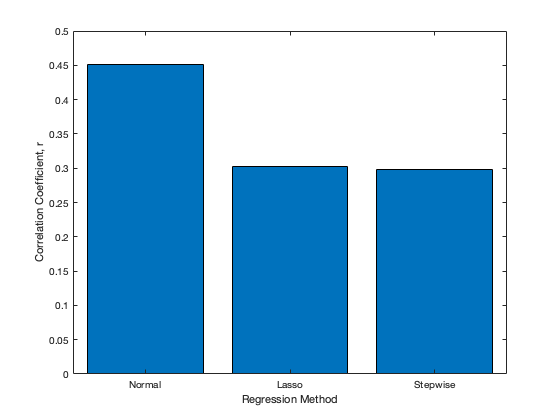

% Create labels for bar graphs
x = categorical({'Normal','Lasso','Stepwise'});
x = reordercats(x,{'Normal','Lasso','Stepwise'});

% Correlation bar graph
bar(x,[r_norm,r_lasso,r_stepwise])
xlabel("Regression Method")
ylabel("Correlation Coefficient, r")